% This code takes as input the SVM results to create different tables and
% figures.

% Last modified: 17/03/2025 by Costanza Armanini

numSubjects = 2; %Number of subjects
numMovements = 49; % Number of movements
numReps = 6; % Number of repetitions
numSensors = 12; % Number of sensors

## Confusion Matrix

totalConfMat = zeros(numMovements, numMovements);

% Aggregate confusion matrices
for subject = 1:numSubjects
    filename = fullfile(sprintf('Results_S%d.mat', subject));
    data = load(filename, 'confMat');
    totalConfMat = totalConfMat + data.confMat;
end

% Calculate the average confusion matrix
averageConfMat = totalConfMat / numSubjects;

% Calculate overall accuracy
correctPredictions = sum(diag(averageConfMat)); % Sum of diagonal elements
totalSamples = sum(averageConfMat(:)); % Sum of all elements
averageAccuracy = (correctPredictions / totalSamples) * 100; % Percentage

% Calculate accuracy for each subclass of exercises

% For movements 1 to 17 (Exercise B)
exBConfMat = averageConfMat(1:17, 1:17);
exBCorrect = sum(diag(exBConfMat)); % Correct predictions for exB
exBTotal = sum(exBConfMat(:)); % Total samples for exB
exBAccuracy = (exBCorrect / exBTotal) * 100; % Percentage for exB

% For movements 18 to 39 (Exercise C)
exCConfMat = averageConfMat(18:39, 18:39);
exCCorrect = sum(diag(exCConfMat)); % Correct predictions for exC
exCTotal = sum(exCConfMat(:)); % Total samples for exC
exCAccuracy = (exCCorrect / exCTotal) * 100; % Percentage for exC

% For movements 40 to 49 (Exercise D)
exDConfMat = averageConfMat(40:49, 40:49);
exDCorrect = sum(diag(exDConfMat)); % Correct predictions for exD
exDTotal = sum(exDConfMat(:)); % Total samples for exD
exDAccuracy = (exDCorrect / exDTotal) * 100; % Percentage for exD

% Display accuracies
fprintf('Overall Accuracy: %.2f%%\n', averageAccuracy);

Overall Accuracy: 80.87%


fprintf('Accuracy for movements 1-17 (ex B): %.2f%%\n', exBAccuracy);

Accuracy for movements 1-17 (ex B): 86.89%


fprintf('Accuracy for movements 18-39 (ex C): %.2f%%\n', exCAccuracy);

Accuracy for movements 18-39 (ex C): 82.84%


fprintf('Accuracy for movements 40-49 (ex D): %.2f%%\n', exDAccuracy);

Accuracy for movements 40-49 (ex D): 89.87%


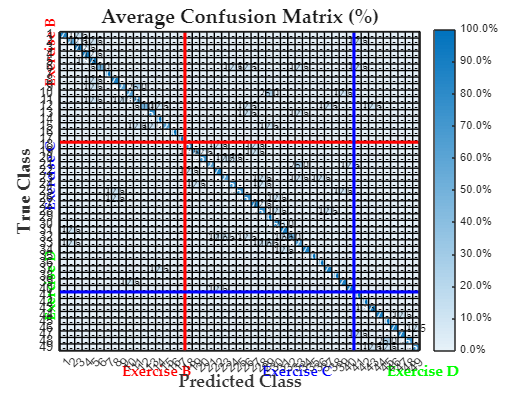

% Confusion matrix in terms of percentages

% Normalize to percentages
percentageConfMat = zeros(numMovements, numMovements); % Pre-allocate matrix
for i = 1:numMovements
    rowSum = sum(averageConfMat(i, :));
    if rowSum ~= 0
        percentageConfMat(i, :) = round((averageConfMat(i, :) / rowSum) * 100, 1); % Round to 1 decimal
    end
end

% Define gesture labels
gestureLabels = arrayfun(@(x) sprintf('%d', x), 1:numMovements, 'UniformOutput', false);

figure;
imagesc(percentageConfMat);
colormap(sky(100)); % Use a better colormap
clim([0, 100]); % Normalize color limits to percentage range
cb = colorbar; % Get the colorbar handle

% Customize colorbar 
cbTicks = cb.Ticks; % Get the colorbar ticks
cb.TickLabels = strcat(arrayfun(@(x) sprintf('%.1f%%', x), cbTicks, 'UniformOutput', false)); % Append % symbol


% Labels and title style
xlh =xlabel('Predicted Class', 'FontName', 'Palatino Linotype', 'FontSize', 14, 'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);
xlh.Position(2) = xlh.Position(2) - 0.3; 
ylh=ylabel('True Class', 'FontName', 'Palatino Linotype', 'FontSize', 14, 'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);
ylh.Position(1) = ylh.Position(1) - 0.3; 
title('Average Confusion Matrix (%)', 'FontName', 'Palatino Linotype', 'FontSize', 16, 'FontWeight', 'bold', 'Color', [0.1 0.1 0.1]);

% Set gestures labels
xticks(1:numMovements);
yticks(1:numMovements);
xticklabels(gestureLabels);
yticklabels(gestureLabels);
ax = gca;
ax.XTickLabelRotation = 45; 
set(gca,'TickLength',[0 0])

% Add values inside each cell, replacing 0s with '-'
[numRows, numCols] = size(percentageConfMat);
for i = 1:numRows
    for j = 1:numCols
        value = percentageConfMat(i, j);
        
        if value == 0
            textColor = 'black'; % Always black for '-'
            text(j, i, '-', 'HorizontalAlignment', 'center', 'FontSize', 9, 'FontName', 'Palatino Linotype', 'Color', textColor);
        else
            textColor = 'black';
            if value > 50  % If the cell has a high percentage, use white text
                textColor = 'white';
            end
            text(j, i, sprintf('%.1f', value), 'HorizontalAlignment', 'center', 'FontSize', 9, 'FontName', 'Palatino Linotype', 'Color', textColor);
        end
    end
end


% Add cell borders
hold on;
for i = 1:numMovements+1
    plot([0.5, numMovements+0.5], [i-0.5, i-0.5], 'k', 'LineWidth', 0.5); % Horizontal lines
    plot([i-0.5, i-0.5], [0.5, numMovements+0.5], 'k', 'LineWidth', 0.5); % Vertical lines
end

% Add thicker colored lines to separate different exercise groups
groupBoundaries = [17, 40]; % Boundary positions for Exercise B, C, and D
boundaryColors = {'r', 'b', 'g'}; 

% Draw boundaries with different colors
for bIdx = 1:length(groupBoundaries)
    b = groupBoundaries(bIdx);
    plot([0.5, numMovements+0.5], [b+0.5, b+0.5], boundaryColors{bIdx}, 'LineWidth', 2.5); % Horizontal separator
    plot([b+0.5, b+0.5], [0.5, numMovements+0.5], boundaryColors{bIdx}, 'LineWidth', 2.5); % Vertical separator
end

% Add text labels for exercise groups on Y axis
text(-1, 9, 'Exercise B', 'FontSize', 12, 'FontWeight', 'bold', 'FontName', 'Palatino Linotype', 'Color', 'r', 'Rotation', 90);
text(-1, 28, 'Exercise C', 'FontSize', 12, 'FontWeight', 'bold', 'FontName', 'Palatino Linotype', 'Color', 'b', 'Rotation', 90);
text(-1, 45, 'Exercise D', 'FontSize', 12, 'FontWeight', 'bold', 'FontName', 'Palatino Linotype', 'Color', 'g', 'Rotation', 90);

% Add text labels for exercise groups on X axis
text(9, numMovements + 3.5, 'Exercise B', 'FontSize', 12, 'FontWeight', 'bold', 'FontName', 'Palatino Linotype', 'Color', 'r');
text(28, numMovements + 3.5, 'Exercise C', 'FontSize', 12, 'FontWeight', 'bold', 'FontName', 'Palatino Linotype', 'Color', 'b');
text(45, numMovements + 3.5, 'Exercise D', 'FontSize', 12, 'FontWeight', 'bold', 'FontName', 'Palatino Linotype', 'Color', 'g');


hold off;

## Average Accuracy, Precision, Recall, F1 score and AUC for each movement

% Initialize variables to store aggregated results
total_precision = zeros(numMovements, numSubjects);
total_recall = zeros(numMovements, numSubjects);
total_F1 = zeros(numMovements, numSubjects);
auc_values = zeros(numMovements, numSubjects);
total_accuracy = zeros(numMovements, numSubjects); % Store movement-wise accuracy

for subject = 1:numSubjects
    filename = fullfile(sprintf('Results_S%d.mat', subject));
    data = load(filename);
    
    total_precision(:, subject) = data.precision;
    total_recall(:, subject) = data.recall;
    total_F1(:, subject) = data.F1;
    total_accuracy(:, subject) = data.movementAccuracy; % Load movement-wise accuracy

    % Calculate AUC for each movement
    for mov = 1:numMovements
        [X, Y, T, AUC] = perfcurve(data.y_test == mov, data.scores(:, mov), 1);
        auc_values(mov, subject) = AUC;
    end
end

% Compute mean values
mean_accuracy = mean(total_accuracy, 2);
mean_precision = mean(total_precision, 2);
mean_recall = mean(total_recall, 2);
mean_F1 = mean(total_F1, 2);
mean_auc = mean(auc_values, 2);
 

% Display table
class_labels = (1:numMovements)';
T = table(class_labels,  mean_accuracy, mean_precision, mean_recall, mean_F1, mean_auc, ...
    'VariableNames', {'Gesture', 'Accuracy', 'Precision', 'Recall', 'F1_Score', 'AUC'});
disp(T);


    Gesture    Precision    Recall    F1_Score      AUC  
    _______    _________    ______    ________    _______

       1           100       87.5      91.667           1
       2        66.667       62.5      61.667     0.96615
       3          87.5       87.5      83.333     0.96615
       4        79.167       87.5        82.5     0.98958
       5        70.833       87.5          75     0.97266
       6            75         50      58.333     0.75391
       7           100        100         100           1
       8        79.167       87.5        82.5     0.89062
       9            75       62.5      66.667      0.8099
      10        58.333       62.5      56.667     0.86068
      11          62.5       62.5      58.333     0.91667
      12            75         50      58.333     0.86458
      13         

% Calculate the overall precision, recall, F1 score and AUC across all
% movements
overallPrecision = mean(mean_precision);
overallRecall = mean(mean_recall);
overallF1 = mean(mean_F1);
overallAUC = mean(mean_auc);

fprintf('Overall average precision across all gestures: %.2f%\n', overallPrecision);

Overall average precision across all gestures: 82.99

fprintf('Overall average recall across all gestures: %.2f%\n', overallRecall);

Overall average recall across all gestures: 80.87

fprintf('Overall average F1 score across all gestures: %.2f%\n', overallF1);

Overall average F1 score across all gestures: 79.37

fprintf('Overall average AUC across all gestures: %.3f%\n', overallAUC);

Overall average AUC across all gestures: 0.952

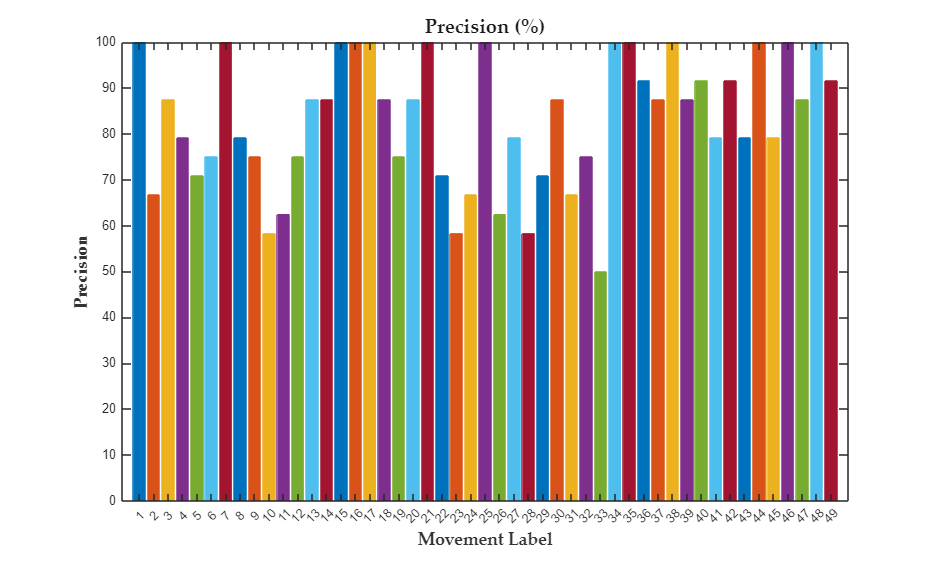

% Create a new figure for precision values
figure;

% Define a colormap
colors = lines(numMovements);

% Plot the median precision values for each movement
for i = 1:numMovements
    bar(i, mean_precision(i), 'FaceColor', colors(i, :), 'EdgeColor', colors(i, :));
    hold on;
end

% Set common y-axis limits
ylim([0 100]);

% Set the x-axis labels
set(gca, 'XTick', 1:numMovements, 'XTickLabel', 1:numMovements);

title('Precision (%)', 'FontName', 'Palatino Linotype', 'FontSize', 16, 'FontWeight', 'bold', 'Color', [0.1 0.1 0.1]);
xlabel('Movement Label', 'FontName', 'Palatino Linotype', 'FontSize', 14, 'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);
ylabel('Precision', 'FontName', 'Palatino Linotype', 'FontSize', 14, 'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);
hold off;

% Adjust the figure size for better visibility
set(gcf, 'Position', [100, 100, 1000, 600]); 
saveas(gcf, 'Precision_All.svg');

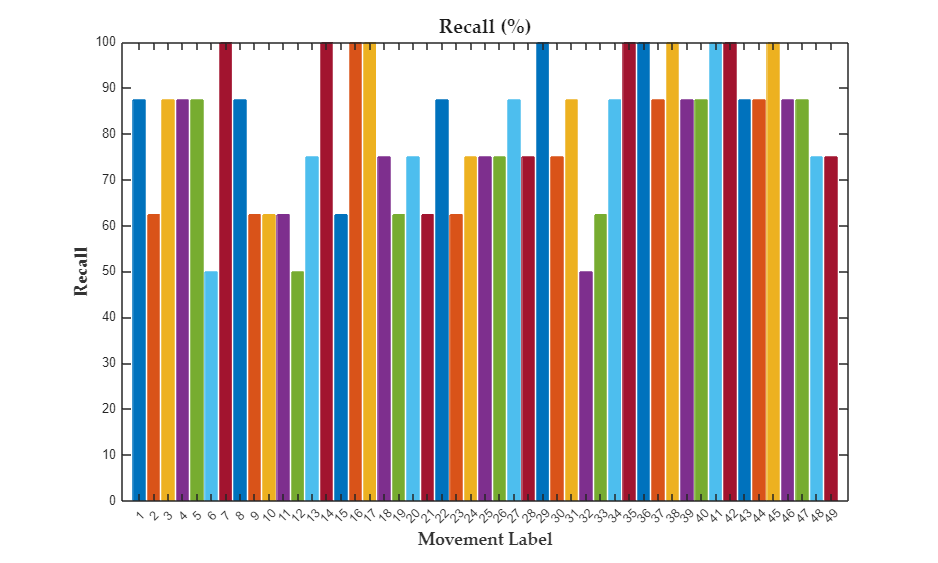

% Create a new figure for recall values
figure;

% Plot the median recall values for each movement
for i = 1:numMovements
    bar(i, mean_recall(i), 'FaceColor', colors(i, :), 'EdgeColor', colors(i, :));
    hold on;
end

% Set common y-axis limits
ylim([0 100]);

% Set the x-axis labels
set(gca, 'XTick', 1:numMovements, 'XTickLabel', 1:numMovements);

title('Recall (%)', 'FontName', 'Palatino Linotype', 'FontSize', 16, 'FontWeight', 'bold', 'Color', [0.1 0.1 0.1]);
xlabel('Movement Label', 'FontName', 'Palatino Linotype', 'FontSize', 14, 'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);
ylabel('Recall', 'FontName', 'Palatino Linotype', 'FontSize', 14, 'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);
hold off;

% Adjust the figure size for better visibility
set(gcf, 'Position', [100, 100, 1000, 600]); % Adjust the figure size as needed
saveas(gcf, 'Recall_All.svg');

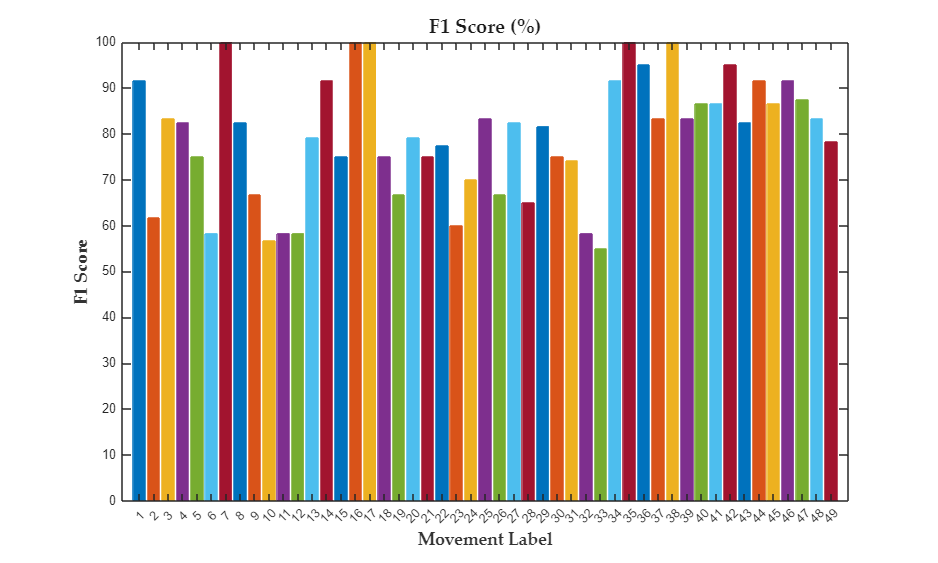

% Create a new figure for F1 score values
figure;

% Plot the median F1 score values for each movement
for i = 1:numMovements
    bar(i, mean_F1(i), 'FaceColor', colors(i, :), 'EdgeColor', colors(i, :));
    hold on;
end

% Set common y-axis limits
ylim([0 100]);

% Set the x-axis labels
set(gca, 'XTick', 1:numMovements, 'XTickLabel', 1:numMovements);

title('F1 Score (%)', 'FontName', 'Palatino Linotype', 'FontSize', 16, 'FontWeight', 'bold', 'Color', [0.1 0.1 0.1]);
xlabel('Movement Label', 'FontName', 'Palatino Linotype', 'FontSize', 14, 'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);
ylabel('F1 Score', 'FontName', 'Palatino Linotype', 'FontSize', 14, 'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);
hold off;

% Adjust the figure size 
set(gcf, 'Position', [100, 100, 1000, 600]); 
saveas(gcf, 'F1_All.svg');

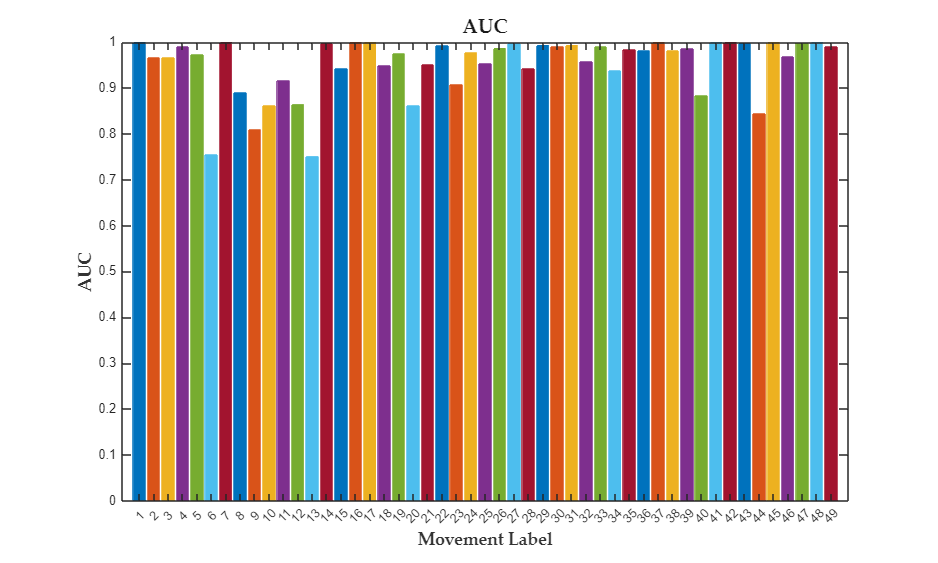

% Create a new figure for AUC values
figure;
for i = 1:numMovements
    bar(i, mean_auc(i), 'FaceColor', colors(i, :), 'EdgeColor', colors(i, :));
    hold on;
end

ylim([0 1]);
title('AUC', 'FontName', 'Palatino Linotype', 'FontSize', 16, 'FontWeight', 'bold', 'Color', [0.1 0.1 0.1]);
xlabel('Movement Label', 'FontName', 'Palatino Linotype', 'FontSize', 14, 'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);
ylabel('AUC', 'FontName', 'Palatino Linotype', 'FontSize', 14, 'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);

set(gca, 'XTick', 1:numMovements, 'XTickLabel', 1:numMovements);
set(gcf, 'Position', [100, 100, 1000, 600]); 
saveas(gcf, 'AUC_All.svg');